# Lab 2 - Visión por Computador

**Juan Carlos Soriano (1493037) - Jorge Giménez (1493035)**

Primeramente, cargamos y mostramos la imagen sobre la que queremos aplicar el algoritmo.

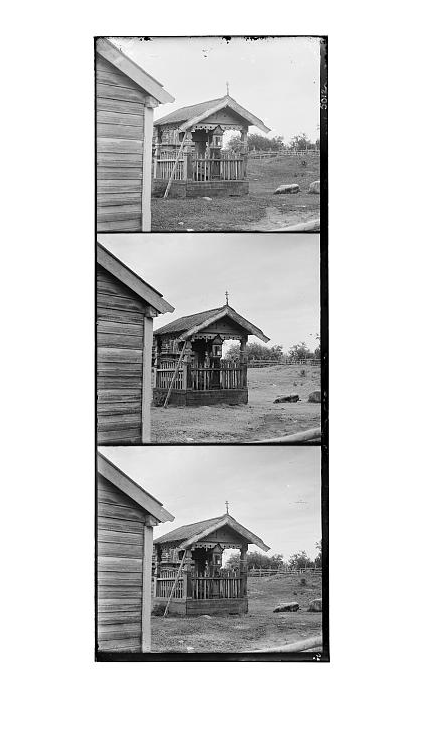

clear
clc

global imageName
imageName = "inputImage2";
imagePath = "./"+ imageName +".jpg";
inputImage = im2double(imread(imagePath));
imshow(inputImage, []);

### 1- Segmentación de las 3 *subimágenes*

El primer paso será conseguir separar las 3 *subimágenes* de la* imagen total* (esta imagen vertical que contiene 3 imágenes más pequeñas dentro suyo que podemos ver al principio del *script* al ejecutarlo).

En el siguiente código se hacen las siguientes asunciones:

- Que las *subimágenes* están eprfectamente colocadas ocupando cada una 1/3 de la *imagen total*.

- Que se ordenan en el orden BGR de arriba hacía abajo (encontraod en la web).

tmp = size(inputImage);
subImageHeight = floor(tmp(1)/3);

channelB = inputImage(1:subImageHeight,:);
channelG = inputImage(subImageHeight+1:subImageHeight*2,:);
channelR = inputImage((subImageHeight*2)+1:subImageHeight*3,:);

Podemos visualizar las 3 *subimágenes *obtenidas mediante esta segmentación tan sencilla:

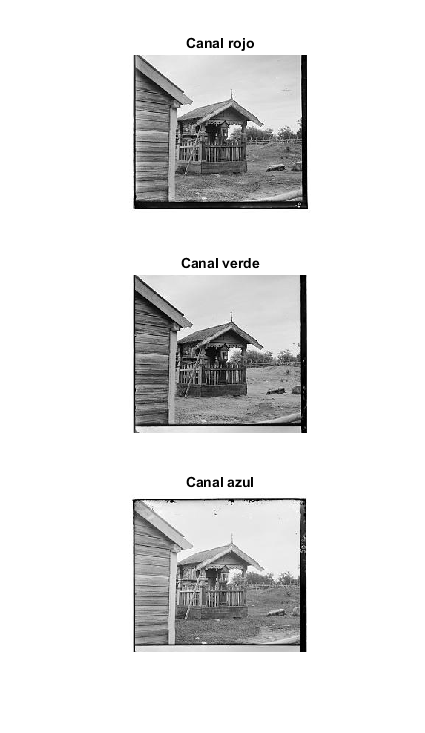

subplot(3, 1, 1);
imshow(channelR);
title("Canal rojo")
subplot(3, 1, 2);
imshow(channelG);
title("Canal verde")
subplot(3, 1, 3);
imshow(channelB);
title("Canal azul")

figure

Si superponemos las imagenes en el orden correcto tal y como las habríamos obtenido ahora, tedríamos el siguiente resultado:

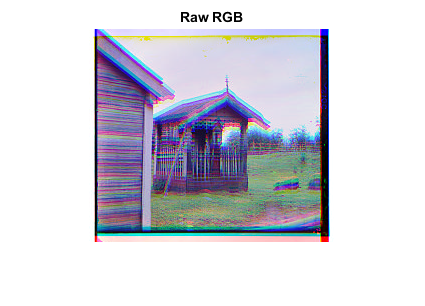

uncenteredComposition = cat(3, channelR, channelG, channelB);
imshow(uncenteredComposition);
title("Raw RGB")

Se puede ver como la imagen toma color pero no se ve demasiado bien debido a que los 3 canales no acaban de estar bien centrados entre si.

### 2- Centrado de las 3 *subimágenes*

% 1 = convolution
% 2 = cross correlation frequency
% 3 = cross correlation freqency / abs
% 4 = normalized cross correlation
% 5 = normalized cross correlation with kernel window
tic
option = 5;
switch option
    case 1
        displacementVectorG = convCorrelation(channelG, channelR);
        displacementVectorB = convCorrelation(channelB, channelR);
        
    case 2
        displacementVectorG = correlationFourier(channelG, channelR);
        displacementVectorB = correlationFourier(channelB, channelR);
        
    case 3
        displacementVectorG = correlationFourierPhase(channelG, channelR);
        displacementVectorB = correlationFourierPhase(channelB, channelR);
        
    case 4
        displacementVectorG = normCrossCorr(channelG, channelR);
        displacementVectorB = normCrossCorr(channelB, channelR);
        
    case 5
        kernelCenter = [140 140];
        kernelRadius = 20;
        tmp = [kernelCenter(1)-kernelRadius, kernelCenter(1)+kernelRadius; kernelCenter(2)-kernelRadius, kernelCenter(2)+kernelRadius];
        kernel = channelR(tmp(1,1):tmp(1,2),tmp(2,1):tmp(2,2));
        displacementVectorG = normCrossCorrKernel(kernel, channelG, kernelCenter);
        displacementVectorB = normCrossCorrKernel(kernel, channelB, kernelCenter);
        
    otherwise
        error("Incorrect Option!");
end

tmp = size(channelR);
maxDisplacementV = max(abs(displacementVectorG(1)), abs(displacementVectorB(1)));
maxDisplacementH = max(abs(displacementVectorG(2)), abs(displacementVectorB(2)));
if(maxDisplacementH == tmp(2))
    maxDisplacementH = 1;
end
if(maxDisplacementV == tmp(1)) 
    maxDisplacementV = 1;
end
finalComposition = zeros(tmp(1), tmp(2), 3);
finalComposition = padarray(finalComposition, [maxDisplacementV maxDisplacementH], 0);

finalComposition(1+maxDisplacementV:maxDisplacementV+tmp(1), 1+maxDisplacementH:maxDisplacementH+tmp(2), 1) = channelR;
finalComposition(1+maxDisplacementV:maxDisplacementV+tmp(1), 1+maxDisplacementH:maxDisplacementH+tmp(2), 2) = channelG;
finalComposition(:,:,2) = circshift(finalComposition(:,:,2), -displacementVectorG);
finalComposition(1+maxDisplacementV:maxDisplacementV+tmp(1), 1+maxDisplacementH:maxDisplacementH+tmp(2), 3) = channelB;
finalComposition(:,:,3) = circshift(finalComposition(:,:,3), -displacementVectorB);

crop = centerCropWindow2d(size(finalComposition), size(channelR));
finalComposition = imcrop(finalComposition, crop);
toc

Elapsed time is 0.041595 seconds.


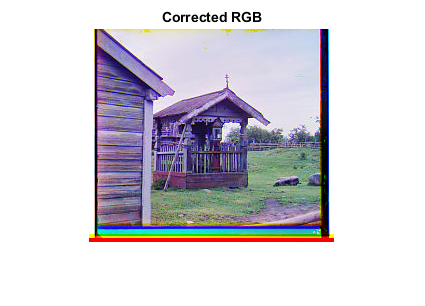

imshow(finalComposition)
title("Corrected RGB")

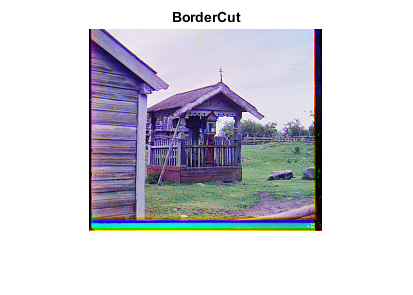


imwrite(finalComposition, "./output/" + imageName + "_colorbase.jpg");

finalCutComposition = cropImage(finalComposition);

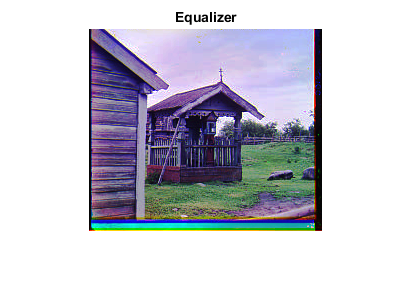


equalizeImage(finalCutComposition);

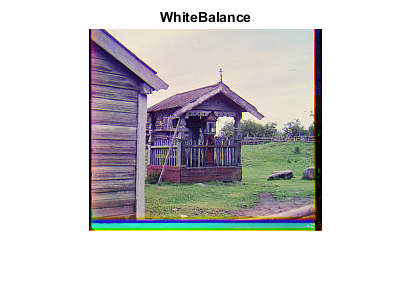


whiteBalance(finalCutComposition);

### Funciones de mejora de imágen

function finalCrop = cropImage(imageUncropped)
global imageName
tmp = size(imageUncropped);
vCrop = uint16(tmp(1)*5/100);
hCrop = uint16(tmp(2)*5/100);
finalCrop = zeros(tmp(1)-vCrop, tmp(2)-hCrop, 3);
crop = centerCropWindow2d(size(imageUncropped), size(finalCrop));
finalCrop = imcrop(imageUncropped, crop);
imshow(finalCrop)
title("BorderCut")
imwrite(finalCrop, "./output/" + imageName + "_colorcrop.jpg");
end

function equalizeImage(finalCutComposition)
global imageName
eq = histeq(finalCutComposition);
imshow(eq)
title("Equalizer")
imwrite(eq, "./output/" + imageName + "_colorequalizer.jpg");
end

function whiteBalance(finalCutComposition)
global imageName
lin = rgb2lin(finalCutComposition);
percentiles = 10;
illuminant = illumgray(lin, percentiles);
linFinal = chromadapt(lin, illuminant, "ColorSpace", "linear-rgb");
linFinal = lin2rgb(linFinal);
imshow(linFinal)
title("WhiteBalance")
imwrite(linFinal, "./output/" + imageName + "_colorwb.jpg");
end

### Funciones de correlación

function displacementVector = correlationFourier(imageChannel, referenceChannel)
fourierR = fft2(referenceChannel);
fourierAlt = fft2(imageChannel);
conjR = conj(fourierR);
corrfft = conjR .* fourierAlt;
corr = real(ifft2(corrfft));
[~ , coordRAlt] = max(corr(:));
[xRAlt, yRAlt] = ind2sub(size(corr),coordRAlt);
displacementVector = [xRAlt yRAlt];
end

function displacementVector = correlationFourierPhase(imageChannel, referenceChannel)
fourierR = fft2(referenceChannel);
fourierAlt = fft2(imageChannel);
crossPwrSpectrum = (fourierAlt .* conj(fourierR)) ./ abs(fourierAlt.*conj(fourierR));
r = ifft2(crossPwrSpectrum);
[~ , coordRAlt] = max(r(:));
[xRAlt, yRAlt] = ind2sub(size(fourierR),coordRAlt);
displacementVector = [xRAlt yRAlt];
end

function displacementVector = normCrossCorr(imageChannel, referenceChannel)
correlation = normxcorr2(referenceChannel, imageChannel);
[~, maxCorrelationIndex] = max(correlation(:));
[v, h] = ind2sub(size(correlation), maxCorrelationIndex);
disp([v,h]);
displacementVector = round([v,h] - size(referenceChannel));
end

function displacementVector = normCrossCorrKernel(kernel, imageChannel, kernelCenter)
correlation = normxcorr2(kernel, imageChannel);
crop = centerCropWindow2d(size(correlation), size(imageChannel));
correlation = imcrop(correlation, crop);
[~, maxCorrelationIndex] = max(correlation(:));
[v, h] = ind2sub(size(imageChannel), maxCorrelationIndex);
displacementVector = round([v,h] - kernelCenter);
end

function displacementVector = convCorrelation(imageChannel, referenceChannel)
correlation = conv2(imageChannel, imrotate(imageChannel, 180), "same");
[~, maxCorrelationIndex] = max(correlation(:));
[v, h] = ind2sub(size(correlation), maxCorrelationIndex);
displacementVector = round([v,h] - size(referenceChannel)/2);
end